%load trained network and treatments
load("neuralnettumor.mat")
MT = imread("Mtreatment.png");
GT= imread("Gtreatment.png");
PT = imread("Ptreatment.png");
%rename network
net= trainedNetwork_2;
%store class labels in 4X1 matrix
name = net.Layers(7).Classes(:,1);
%make imagedatastore from each subfolder
ds = imageDatastore("image*.jpg");
%augment imagedatastore to have correct image input values for the network
ads = augmentedImageDatastore([227 227],ds);
%give prediction classification and score of the given dataset
[prediction, scores] = classify(net,ads)

prediction = 16×1 categorical array
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     glioma_tumor 
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     pituitary_tumor 
     glioma_tumor 


scores = 16×4 single matrix
     0     0     0     1
     0     0     0     1
     0     0     0     1
     0     0     0     1
     0     0     0     1
     1     0     0     0
     0     0     0     1
     0     0     0     1
     0     0     0     1
     0     0     0     1


Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 


Glioma tumor diagnosed. The treatment is : 


Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 
Pituitary tumor diagnosed. The treatment is : 


Glioma tumor diagnosed. The treatment is : 


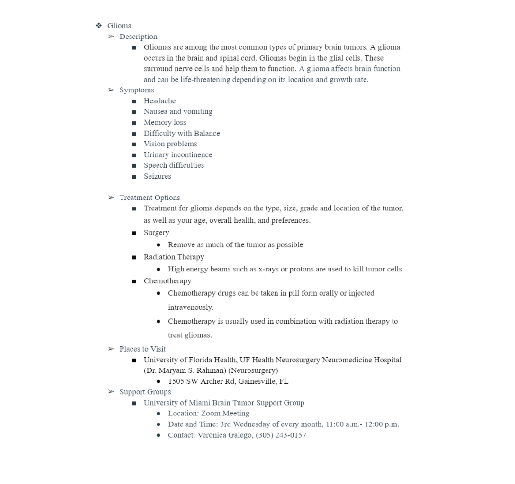


%for loop to see if correct label detected
for i =1:16
    %see if prediction value equals the correct label
if prediction(i,1) == name(1,1)
    fprintf("Glioma tumor diagnosed. The treatment is : \n")
    imshow(GT)
elseif prediction(i,1) == name(2,1)
 fprintf("M tumor diagnosed. The treatment is : \n")
 imshow(MT)
 elseif prediction(i,1) == name(3,1)
 fprintf("No tumor diagnosed. No treatment required \n")
 
 elseif prediction(i,1) == name(4,1)
 fprintf("Pituitary tumor diagnosed. The treatment is : \n")
 imshow(PT)
end
end